### Profile_1

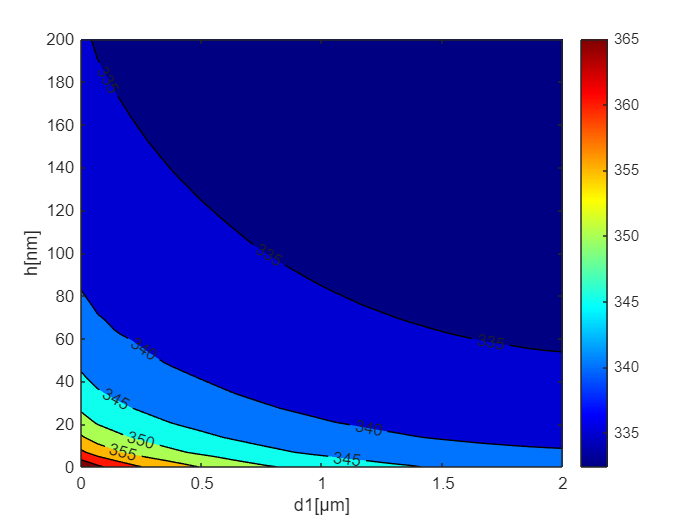

load('plots.mat',"X","Y","Z");
[c,h]=contourf(X,Y,Z);colorbar;colormap("jet")
xlabel('d1[µm]');ylabel('h[nm]');clabel(c,h);

### Profile_2a

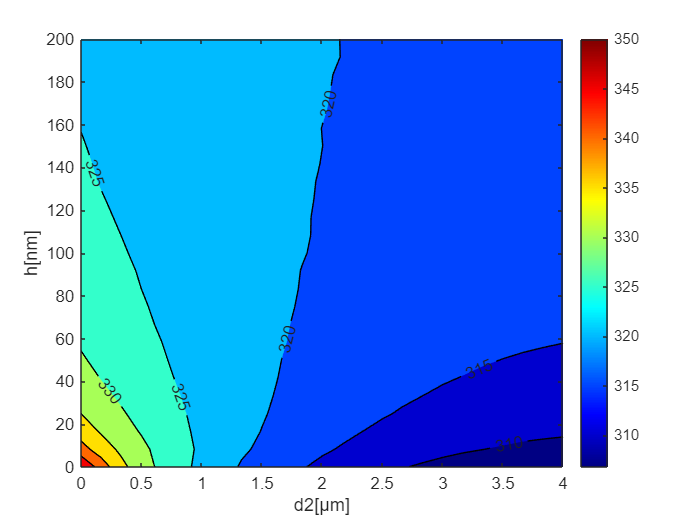

load("plots.mat","X2","Y2","Z2");
[c,h]=contourf(X2,Y2,Z2);colorbar;colormap("jet")
xlabel('d2[µm]');ylabel('h[nm]');clabel(c,h);

### Profile_2b

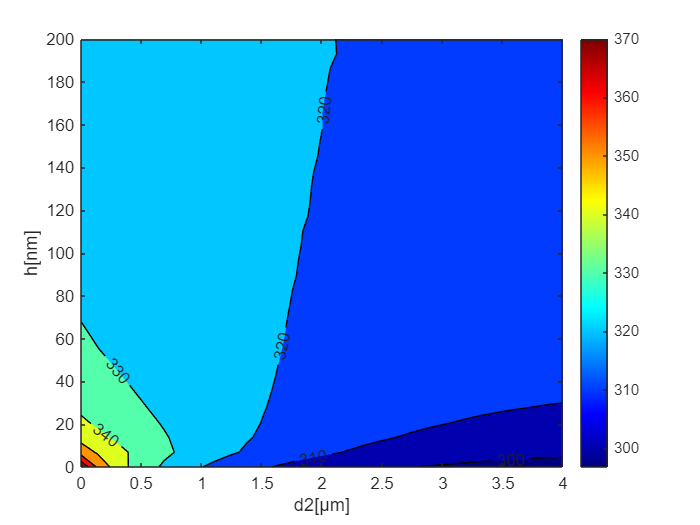

load('plots.mat','X3','Y3','Z3')
[c,h]=contourf(X3,Y3,Z3);colorbar;colormap("jet")
xlabel('d2[µm]');ylabel('h[nm]');clabel(c,h);

### Loss Factor (Profile 1)

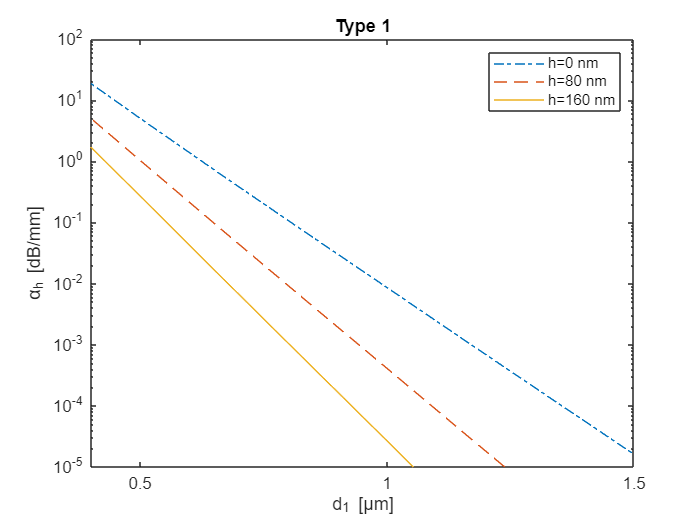

load("plots.mat",'x','y1','y2','y3');
semilogy(x,y1,'-.','DisplayName','h=0 nm');
hold on
semilogy(x,y2,'--','DisplayName','h=80 nm');
semilogy(x,y3,'DisplayName','h=160 nm');
title('Type 1')
hold off
legend
xlabel('d_1 [µm]');ylabel('α_h [dB/mm]')
ylim([10^-5,10^2])
xlim([0.4,1.5])

### Loss Factor (Profile 2)

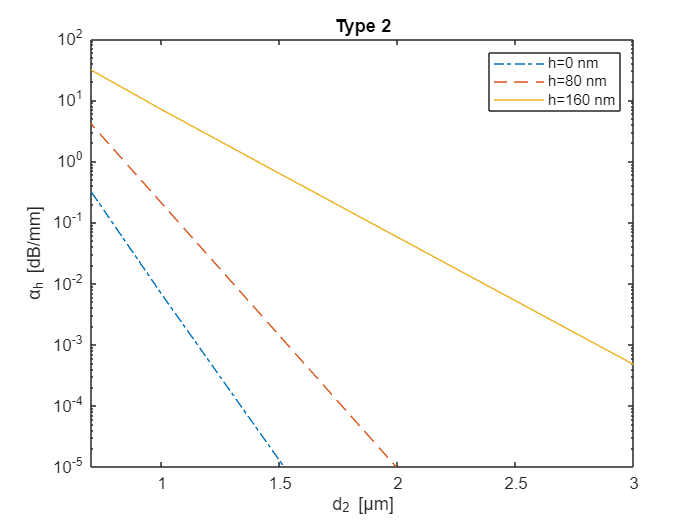

load('plots.mat','x_0','y_1','y_2','y_3');
semilogy(x_0,y_1,'-.','DisplayName','h=0 nm');
hold on
semilogy(x_0,y_2,'--','DisplayName','h=80 nm');
semilogy(x_0,y_3,'DisplayName','h=160 nm');
hold off
legend
title('Type 2')
xlabel('d_2 [µm]');ylabel('α_h [dB/mm]')
xlim([0.7,3]);
ylim([10^-5,10^2]);

### Sensitivity Plot

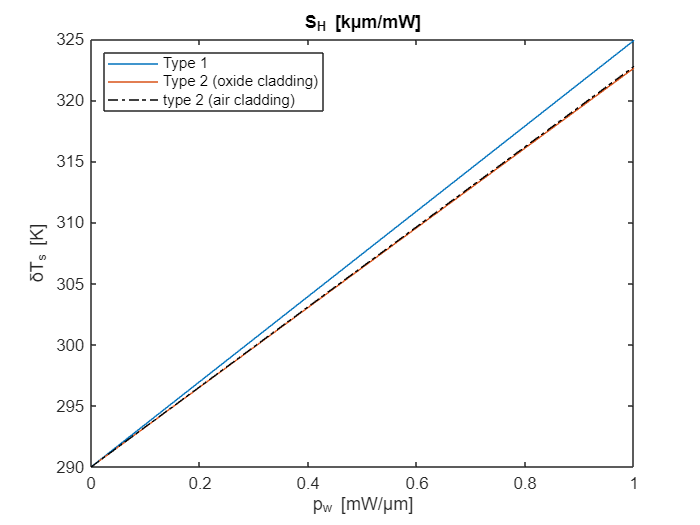

% data imported from ansys HEAT simulation.
y11=[290 296.978 303.955 310.932 317.908 324.885];
x1=[0 0.2 0.4 0.6 0.8 1];
y2a=[290 296.526 303.051 309.576 316.101 322.626];
x2a=[0 0.0002 0.0004 0.0006 0.0008 0.001];
x2a=x2a*10^3;
y2b=[290 296.552 303.103 309.655 316.206 322.757];
x2b=x2a;
figure
plot(x1,y11,'DisplayName','Type 1');
hold on
plot(x2a,y2a,'DisplayName','Type 2 (oxide cladding)');
plot(x2b,y2b,'-.','DisplayName','type 2 (air cladding)','Color','black');
hold off
title('S_H [kµm/mW]')
xlabel('p_w [mW/µm]');ylabel('δT_s [K]')
legend('Location','northwest');

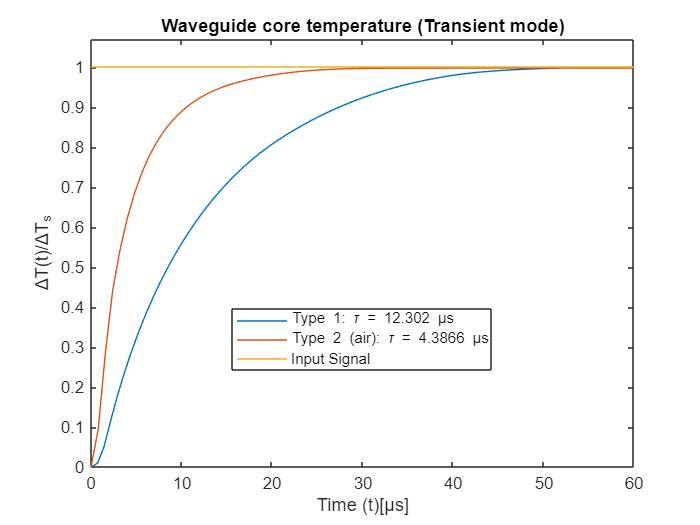

load('plots.mat','T_1','T_2','T_3');
t=linspace(0,60,85);
%t2=linspace(0,60,83);
t3=linspace(0,60,76);
plot(t,T_1,'DisplayName','Type 1: \tau = 12.302 µs');
hold on
plot(t3,T_3,'DisplayName','Type 2 (air): \tau = 4.3866 µs')
%plot(t2,T_2,'DisplayName','Type 2 (oxide cladding): \tau = 11.2447 µs')
plot([0,60],[1,1],'DisplayName','Input Signal')
hold off
ylim([0,1.07]);
xlabel('Time (t)[µs]');ylabel('\DeltaT(t)/\DeltaT_s')
title('Waveguide core temperature (Transient mode)')
legend('Location','best')